clear all;
close all;

# **Properties of water and gravity**

Density of water $\left[\frac{kg}{m^3}\right]$:

rho = 1000;

Heat capacity of water $\left[\frac{j}{kg\cdot K}\right]$:

c_p = 4200;

Gravitational acceleration $\left[\frac{m}{s^2}\right]$:

g   = 9.81;

# **Tank 1**

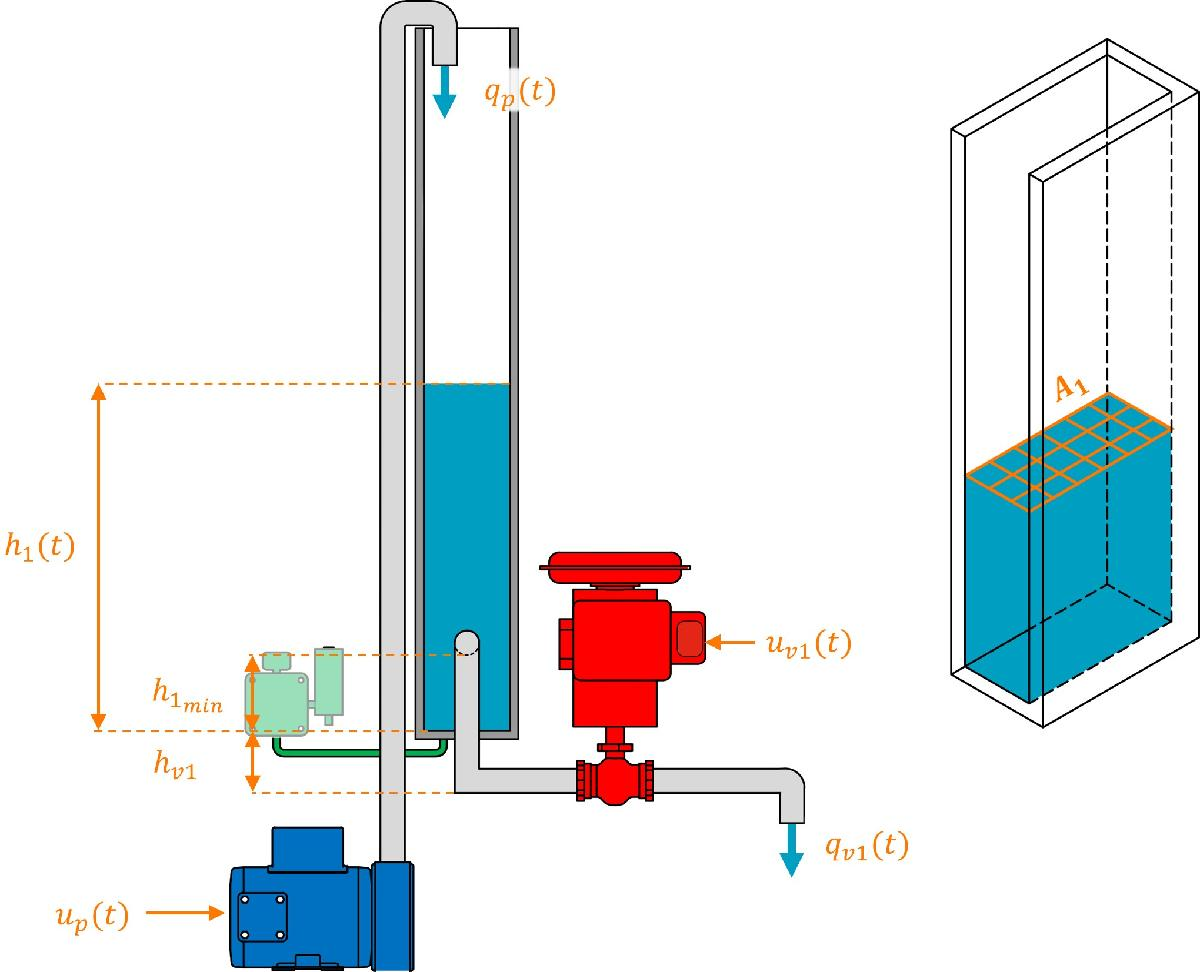

Height from the bottom of tank 1 to valve 1 $\left[m\right]$:

h_v1=0.05;

Maximum height of tank 1 $\left[m\right]$:

h1_max=1;

Minimum height of tank 1 $\left[m\right]$:

h1_min=0.13;

Area of tank 1 $\left[m^2\right]$:

A1=0.01;

# **Tank 2**

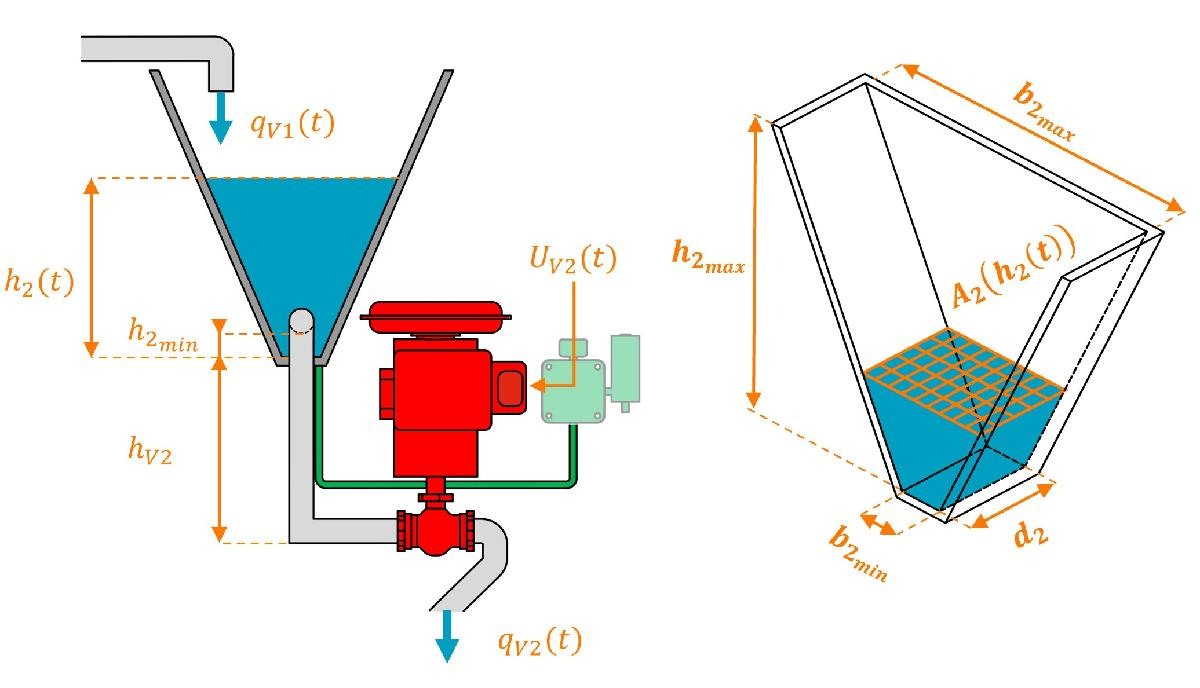

Height from the bottom of tank 2 to valve 2 $\left[m\right]$:

h_v2=0.25;

Maximum height of tank 2 $\left[m\right]$:

h2_max=0.4;

Minimum height of tank 2 $\left[m\right]$:

h2_min=0.02;

# **Load logged inputs and measurements**

Select dataset:

load("dataset2.mat")

# **Pump characteristics**

Pump action $\left[-\right]$:

u_p = [0.00  0.45  0.46  0.47  0.48  0.49  0.50  0.55...
           0.60  0.65  0.70  0.75  0.80  0.85  0.90  0.95  1.00];

Volumetric flow from the pump $\left[\frac{m^3}{s}\right]$:

q_p = [0.00  0.00  1.25  2.25  3.15  3.75  4.40  6.75...
           8.75 10.70 12.25 13.75 15.15 16.50 18.00 19.20 20.00];

Convert volumetric flow from $\left[\frac{l}{h}\right]$ to $\left[\frac{m^3}{s}\right]$:

q_p = q_p/60000;

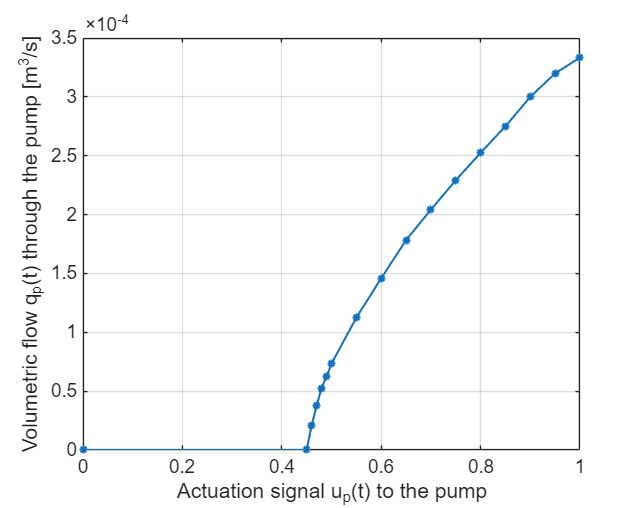

figure('Name','Pump characteristic')
myPlot(u_p, q_p)
xlabel('Actuation signal u_{p}(t) to the pump')
ylabel('Volumetric flow q_{p}(t) through the pump [m^3/s]')

# **Valve characteristics**

Valve constant for valve 1 at a 1-bar pressure drop$\left[\frac{m^3}{h}\right]$:

k_v1=99e-7;
k_v2=99e-7;

Logged data:

u_v1 = 0:0.03:1;
f_v1 = (exp(u_v1.^1.2)-1)/(exp(1)-1);
u_v2 = u_v1;
f_v2 = f_v1;

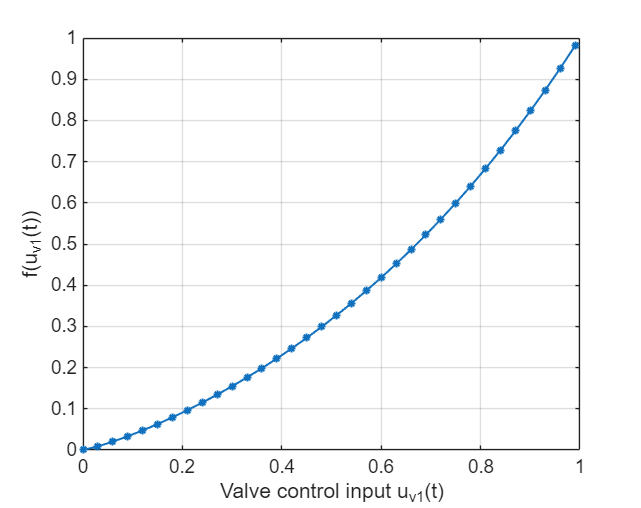

figure('Name','valve characteristics')
myPlot(u_v1,f_v1)
xlabel('Valve control input u_{v1}(t)')
ylabel('f(u_{v1}(t))')

function myPlot(x, y, xlims, ylims)
    fig=gcf;
    fig.Position = [1825 578 641 508];

    % Plot step response
    plot(x, y,'*-', 'LineWidth', 1.5);
    grid on;

    set(gca,'FontSize',14);
    hold on;

end